## MATLAB Least Squares Regression

In this livescript, you will learn how

- To perform least squares regression using inbuilt MATLAB functions.

Consider the data set

x = [0.6939    2.0925    3.3455    4.1205    4.8542    6.1242    6.9356    8.3777    8.8859   10.1363];
y = [3.7744    8.0446   16.9718   23.9429   32.5361   52.6056   60.2304   81.6795   94.6263  115.0161];

To perform a regression analysis, it's typically a good idea to plot the data on a scatter plot to get an idea of what it looks like

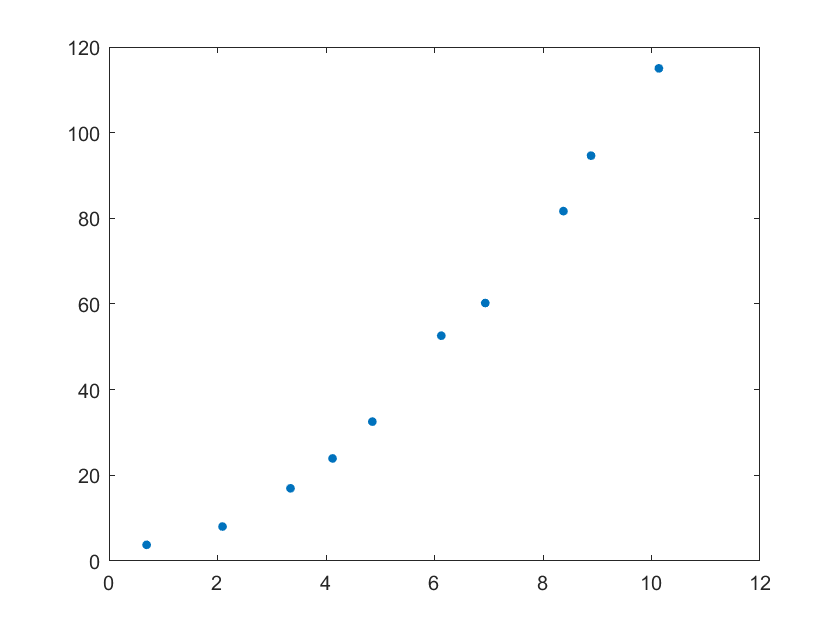

plot(x,y,'.','MarkerSize',15)

From the looks of it, the data seems quite linear, so let's begin by fitting a linear model.

### Graphical Curve Fitting

The simpliest way of we can use the 'Basic Fitting' toolbox.

To do this, we first plot the data as usual.

figure('Visible',"on")
plot(x,y,'.','MarkerSize',15)

To use the toolbox, you need to navigate to the tools menu, then the Basic Fitting tab.

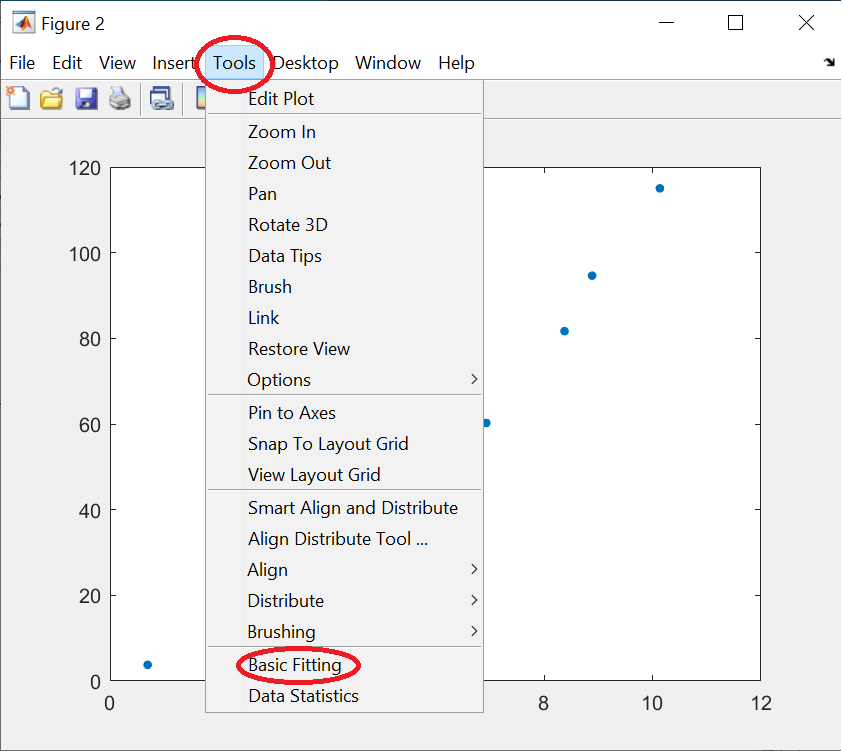

(a)        Using the Basic Fitting toolbox, fit a linear curve to the data provided.

For more advanced curvefitting, we can call the Curve Fitting Toolbox from the command line using $\texttt{cftool}$.

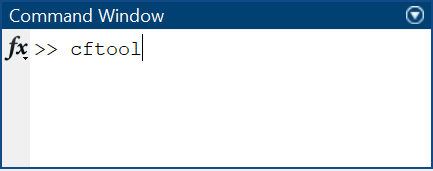

(b)        Use $\texttt{cftool}$ to fit a linear curve to the $\texttt{x}$ and $\texttt{y}$.

### Curve fitting from the command window

In MATLAB, there are a number of ways to do this, the easiest begin $\texttt{fitlm}$ which takes the $\texttt{x}$ and $\texttt{y}$ values as inputs and outputs the parameters for a linear model.

fitlm(x,y)

(c)        Run this command.

The outputs are quite convoluted, with many statistical measures, but it is good for more advanced analyses.

If you know the form of the model, it is also possible to conduct a fit from the command line.

The function $\texttt{polyfit(xval,yval,n)}$ is great for polynomial fitting. It takes inputs in the form of the $\texttt{x}$ and $\texttt{y}$ values, in addition to the order ($n$) of the polynomial that we'd like to use.

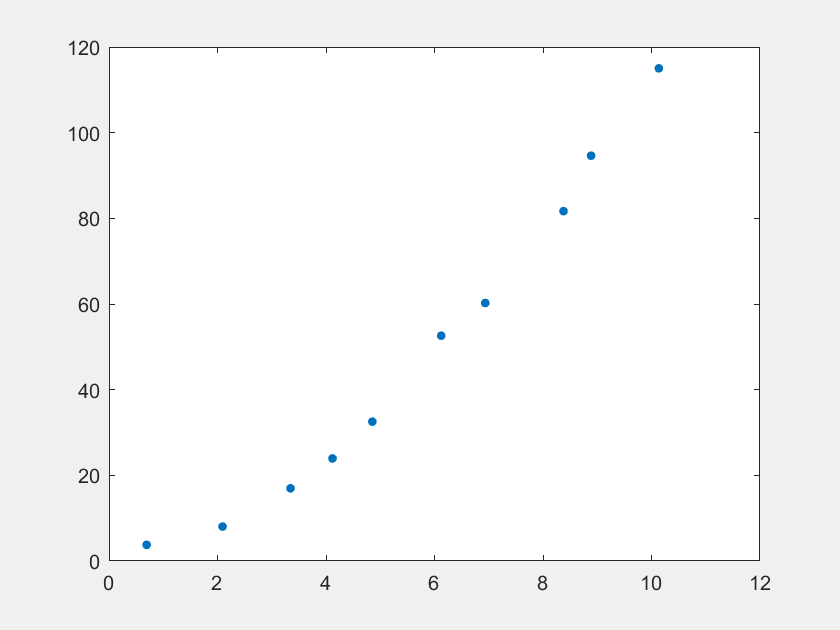

a = polyfit(x,y,1)

(d)        Run this command.

**NOTE**: If we specify $n$ as the $p-1$, where $p$ is the number of points in our data set, $\texttt{polyfit}$ provides the interpolating polynomial of order $p-1$.

You would have noticed that the function outputs a vector of two values. These are infact the coefficients of the linear function


$$y=a_{1}x+a_{0}$$


And we can evaluate this function using $\texttt{polyval}$. We just have to provide an input of the polynomial coefficients and a point, say $x=5.5$.

polyval(a,5.5)

(e)        Run this command.

For more general fitting, MATLAB has the function $\texttt{fit(x,y,fitType)}$. It takes the column vectors $\texttt{x}$ and $\texttt{y}$, and a model to fit this data against.

These include:

- `'poly1'           `Linear polynomial curve

- `'poly2'           `Quadratic polynomial curve

- `'linearinterp'    `Piecewise linear interpolation

- `'cubicinterp'     `Piecewise cubic interpolation

- `'smoothingspline' `Smoothing spline (curve)

- `'lowess'          `Local linear regression (surface)

So for our model, we have

fit(x',y','poly1')

a =    12.2362  -19.0490


(f)        Run this command and see if it gives the same predictions as before.

If you want more general functions, you can specify these inside $\texttt{fit}$. 

For example, if we wanted to fit a power function of the form


$$y=ax^{b}$$


then we can run the command

fit(x',y','a*x^b')

ans = 48.2498

ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       12.24  (10.23, 14.25)
       p2 =      -19.05  (-31.66, -6.435)

ans =      General model:
     ans(x) = a*x^b
     Coefficients (with 95% confidence bounds):
       a =       2.313  (1.815, 2.811)
       b =       1.689  (1.588, 1.789)

(g)        Run this command